**600100 ACW - Star Fish Detector - Daniel Wilde**

disp("Computer Vision Course Work")

Computer Vision Course Work


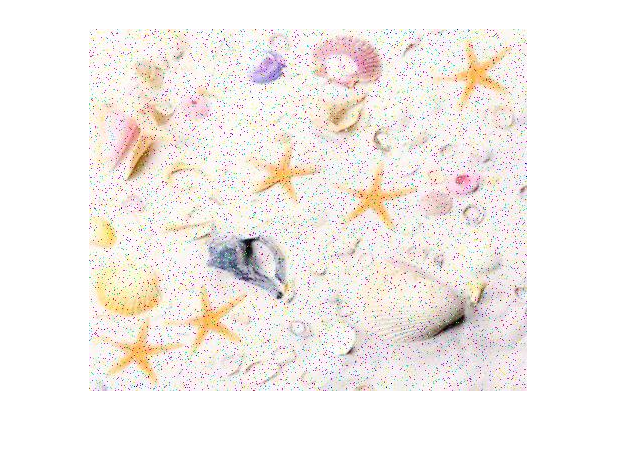

Enhancing Image...
Image has been enhanced.


Error using conv2
N-D arrays are not supported.

Error in star_fish_detector_v0>Enhancement (line 7)
    out = conv2(img,filter, "full");

Error in star_fish_detector_v0>ImagePipeLine (

ImagePipeLine("../images/starfish.jpg")

function out = Enhancement(img)
    disp ("Image has been enhanced.")
    filter = [1:3; 1:3; 1:3];
    out1 = conv2(img(1,1,1:256),filter, "full");
end

function out = ExtractFeatures(img)
    disp("Features have been extracted.")
end

function ImagePipeLine(name)
    %loading in the image
    img = imread(name);
    imshow(img)
    
    %Image Processing
    disp("Enhancing Image...")
    out = Enhancement(img);
    disp(out)
    
    disp("Extracting Features...")
    ExtractFeatures(img)
    disp(out)
    
    
    x = (5);
    fprintf('There are %6.2f starfish. \n',x);
end